cd 'C:\Users\root\Documents\00phd\00Measurement\Continuous-distance-NF-HRTF\220619ContinuousDistanceHRTFKU100\measurementdata\220929microphonetest'

## define some parameters

fs=48000; 
winL=40;      % window length
Ntarget=128;  % target output length

## import recordings

binLdata=importdata('bin_L.mat');
binRdata=importdata('bin_R.mat');
meadata=importdata('mea.mat');

binL=cell2mat(binLdata.ImpulseResponse(4,2));
binR=cell2mat(binRdata.ImpulseResponse(4,4));
mea=cell2mat(meadata.ImpulseResponse(4,2));

## plot raw signals

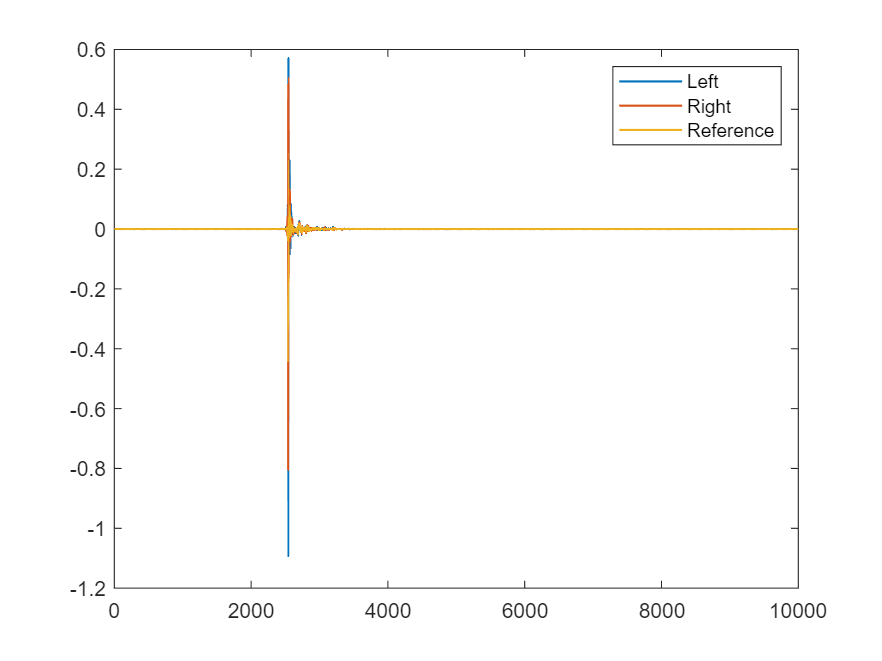

figure
plot(binL,'LineWidth',1);hold on;
plot(binR,'LineWidth',1);hold on;
plot(mea,'LineWidth',1);hold on;
legend('Left','Right','Reference');
xlim([0 10000]);

## normalize reference signal

mea=mea/max(abs(mea));

## windowing

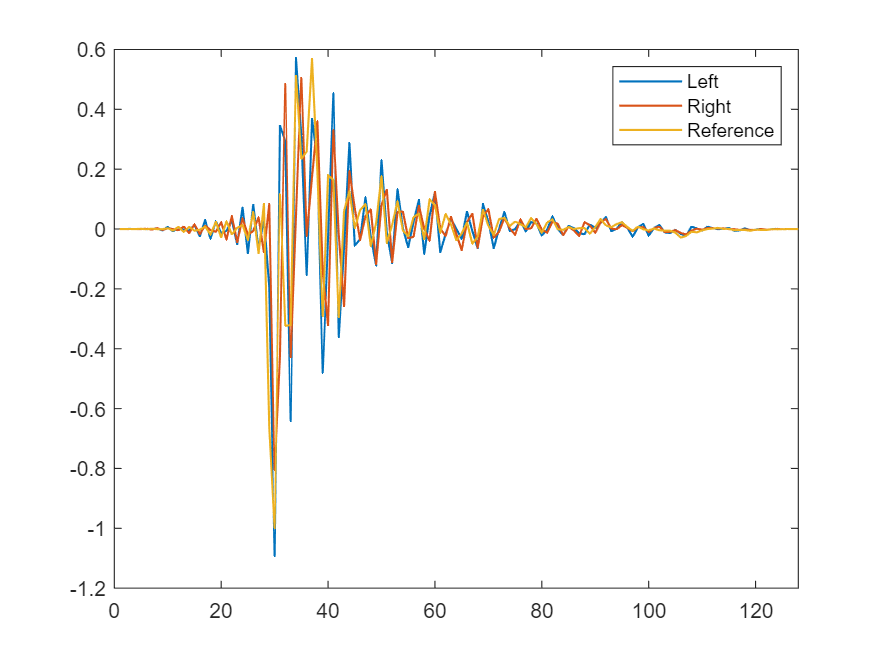

[binLwin,~]=Windowing(binL,Ntarget,winL,10);
[binRwin,~]=Windowing(binR,Ntarget,winL,10);
[meawin,~]=Windowing(mea,Ntarget,winL,10);

% plot windowed signal
figure
plot(binLwin,'LineWidth',1);hold on;
plot(binRwin,'LineWidth',1);hold on;
plot(meawin,'LineWidth',1);hold on;
legend('Left','Right','Reference');
xlim([0 Ntarget]);

## Compute Corrector Transfer Function

[~,ymL]=rceps(binLwin);
[~,ymR]=rceps(binRwin);

HcorrL=fft(meawin)./fft(ymL);
HcorrR=fft(meawin)./fft(ymR);

hcorrL=ifft(HcorrL,'symmetric');
hcorrR=ifft(HcorrR,'symmetric');

hcorrL=lowpass(hcorrL,21000,fs);
hcorrR=lowpass(hcorrR,21000,fs);

HcorrL=fft(hcorrL);
HcorrR=fft(hcorrR);

figure
plot(hcorrL,'LineWidth',1);hold on;
plot(hcorrR,'LineWidth',1);hold on;
legend('Left','Right');
xlim([0 Ntarget]);

faxis=[0:floor(Ntarget/2)]/Ntarget*fs;
HcorrLplot=2*HcorrL([1:floor(Ntarget/2)+1]);
HcorrRplot=2*HcorrR([1:floor(Ntarget/2)+1]);
HcorrLplot(1)=HcorrLplot(1)/2;
HcorrRplot(1)=HcorrRplot(1)/2;
figure
set(gcf,'Units','Normalized');
set(gcf,'Position',[0.1 0.1 0.6 0.4]);
plot(faxis,20*log10(abs(HcorrLplot)),'LineWidth',1);hold on;
plot(faxis,20*log10(abs(HcorrRplot)),'LineWidth',1);hold on;
legend('Left','Right');
ax=gca;
ax.XScale='log';
xlim([300 20000]);